# Newton's Law of Cooling 

## Task 1

The temperature of a pie cooling to room temperature after being taken out of an oven is given by

dT/dt=c(T−23)  where c=−0.028.

When the pie is removed from the oven (t=0 minutes), the pie's temperature is 175∘C. 

Task

Write a script to determine the temperature of the pie over time and plot the result by completing the following steps:

1. Create a variable `tRange` for the time interval t=0 to 100 minutes.

2. Create a variable `T0` for the initial temperature, T(0)=175.

3. Write a local function named `pieODEfun` to represent the ODE.

4. Call `ode45` to solve the differential equation, assigning the outputs to the variables `tSol` and `TSol`.

5. Plot `TSol` as a function of `tSol`.

Solve the ODE and plot the solution.

*Remember to define your ODE function at the bottom of this script.*

tRange=[0 100]

tRange =      0   100


T01=175

T01 = 175

[tSol,TSol]=ode45(@pieODEfun,tRange,T01)

tSol =          0
    2.0657
    4.1314
    6.1971
    8.2628
   10.7628
   13.2628
   15.7628
   18.2628
   20.7628


TSol =   175.0000
  166.4578
  158.3956
  150.7866
  143.6052
  135.4515
  127.8490
  120.7606
  114.1515
  107.9890


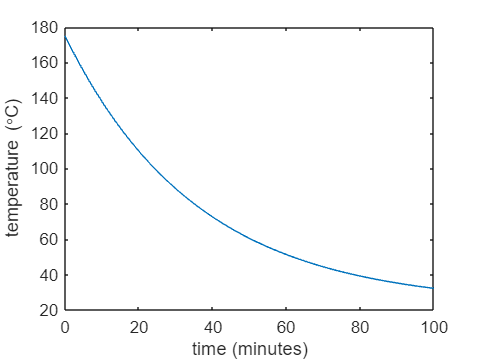

plot(tSol,TSol)


% Label axes
xlabel("time (minutes)")
ylabel("temperature (\circC)")

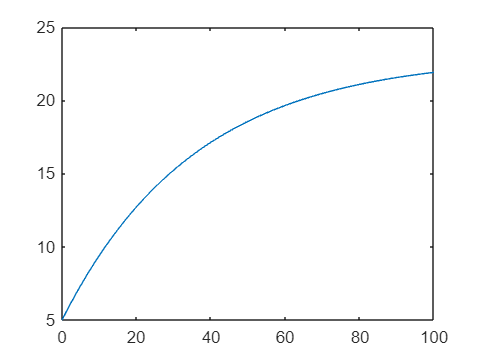

T01 = 5;
[tSol,TSol] = ode45(@pieODEfun,tRange,T01);
plot(tSol,TSol)

## Task 1 (continued)

Define the ODE function for   where  -0.028.

function dTdt=pieODEfun(t,T)
c=-0.028;
dTdt=c.*(T-23);
end

The pie approaches room temperature quickly at first, and more slowly as its own temperature nears that of the room. 

The same differential equation can be used if the pie was removed from the  refrigerator instead of the oven, by modifying just the initial  condition.